# HomeWork 4

Lin Zhao(linzhao@kth.se), Ning Wang(ningwa@kth.se)

### Task 1

### **Sliding mode control**

Define the sliding surface s(x)=γx1+x2=0. Derive a sliding mode controller on the form u=−β(x)sgn(s(x)) that is guaranteed stable for any a∈(0.5,1.5). Approximate the sign function with a saturation: sgn(s)≈sat(s/0.1). Tune it so that the input stays within its bounds when the system is started at x1(0)=π/6 and x2(0)=0, (for 𝑎=1a=1). Simulate the system and plot the states, the input and the function s(x) over time. Discuss the results.

**Solution: **

Firstly we convert the system to the standard form for robust sliding mode control:


$$\dot{x}_{1}=x_{2}\\\dot{x}_{2}=f(x)+g(x)u$$


In which 


$$f(x)=asin(x_{1})\\g(x)=acos(x_{1})$$


Now that $|x_{1}|<\pi/2$


$$g(x)>0$$



$$|\frac{\gamma x_{2}+f(x)}{g(x)}|\leq \rho(x)=\frac{\gamma|x_{2}|}{0.5cos(x_{1})}+tan(x_{1})$$


Then we can take


$$s(x)=\gamma x_{1}+x_{2}$$



$$\dot{V}=s\dot{s}=s(\gamma x_{2}+f(x))+sg(x)u\\=s\frac{\gamma x_{2}+f(x)}{g(x)}g(x)+sg(x)u\\\leq|s||\frac{\gamma x_{2}+f(x)}{g(x)}|g(x)+sg(x)u\\\leq|s|\rho(x)g(x)+sg(x)u$$


Then, by choosing 


$$u=-\beta(x)sgn(s)$$



$$\beta(x)=\rho(x)+\beta_{0}$$


We have 


$$\dot{V}\leq|s|g(x)(\rho(x)-\beta(x))\\\leq-|s|g(x)\beta_{0}\\<0$$


In this case, approximate the sign function with a saturation:sgn(s)≈sat(s/0.1). 

The control parameters are set as  $\gamma=1\\\beta_{0}=1$

The initial state is set as


$$x_1(0)=\pi/6\\x_2(0)=0$$


The simulation result is ploted as below. It is shown that $x_{1}$ and $x_{2}$ both converge to the zero equilibrium point after about 6 seconds, the sliding surface s(x) also converges to zero. During tuning, we found that a larger $\gamma$ makes the state variables converge faster, but a severe oscillation occurs in $x_{2}$. In the design of the control system, we didn't use the true value for a, so the control design is robust.

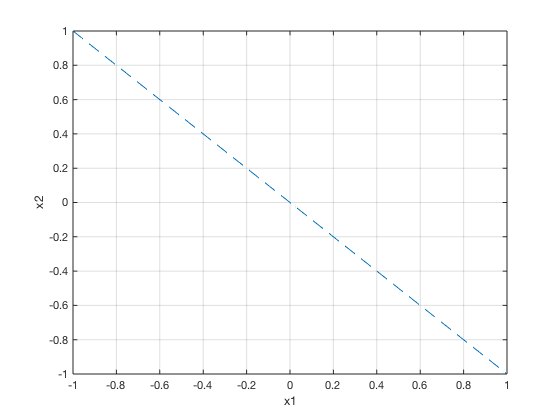


clear;
clc;

a=1;
gamma=1;
mu=1;
 sat=@(u)min(1,max(-1,u));
s=@(x)gamma*x(1,:)+x(2,:);
f=@(x,u)[x(2,:);a*(sin(x(1,:))+u*cos(x(1,:)))];
u=@(x) sat(-(gamma.*abs(x(2,:))./(0.5.*cos(x(1,:)))+tan(x(1,:))+1).*sat(s(x)/0.1)/2)*2;
x0=[pi/6,0];
tfinal=20;
sol=ode45(@(t,x)f(x,u(x)),[0,tfinal],x0);
t=linspace(0,tfinal,200);
x=deval(sol,t);
figure(1)
% u(x)=((1./(a*cos(x(1,:))).*(-gamma.*x(2,:)-a*sin(x(1,:)))-1).*sat(s(x)./0.1));
fimplicit(@(x1,x2) gamma.*x1+x2,[-1,1],'--') 
xlabel('x1');
ylabel('x2');
grid on;

%%

**Figure 1. Relation between x1 and x2 for s(x) **

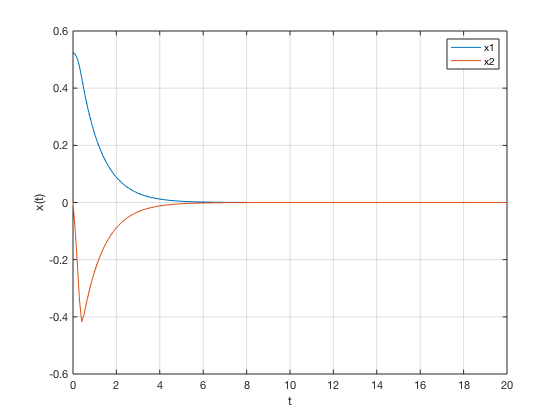

figure(2);
plot(t,x(1,:),t,x(2,:));
legend('x1','x2');
xlabel('t')
ylabel('x(t)')
grid on;

**Figure 2. States x1 and x2 over time**

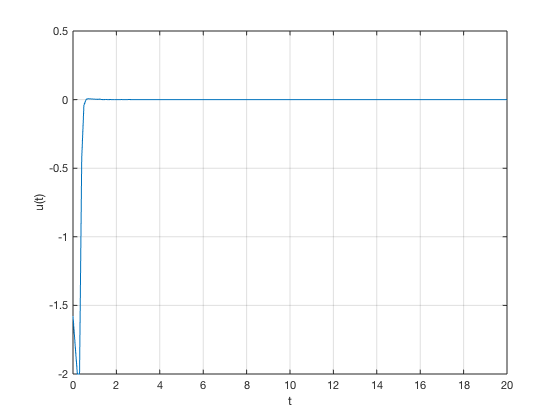

figure(3)
plot(t,u(x));
xlabel('t')
ylabel('u(t)')
grid on;

**Figure 3. Control input u(x) over time**

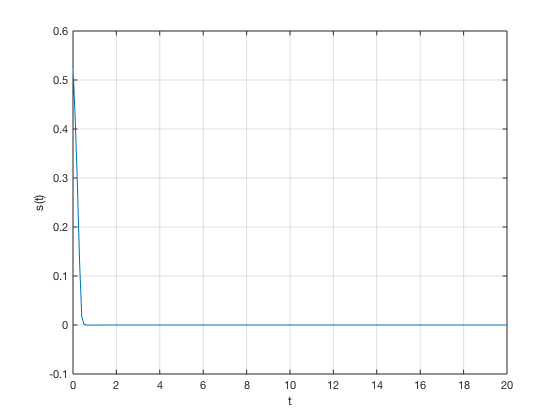

figure(4)
plot(t,s(x));
xlabel('t')
ylabel('s(t)') 
grid on;

**Figure 4. Function s(x) over time**